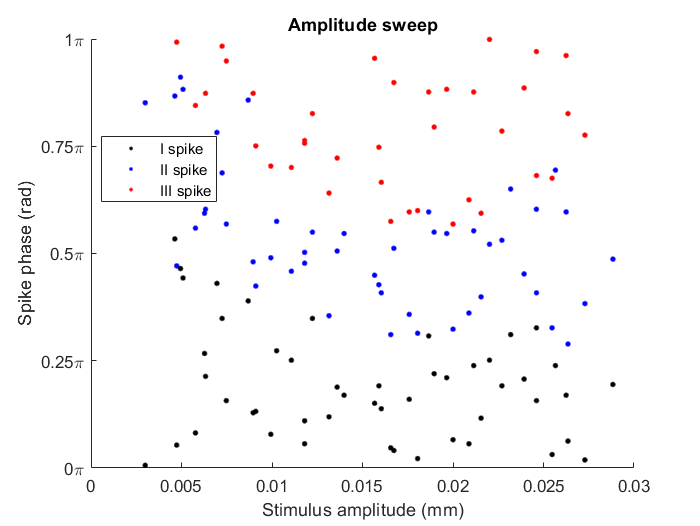

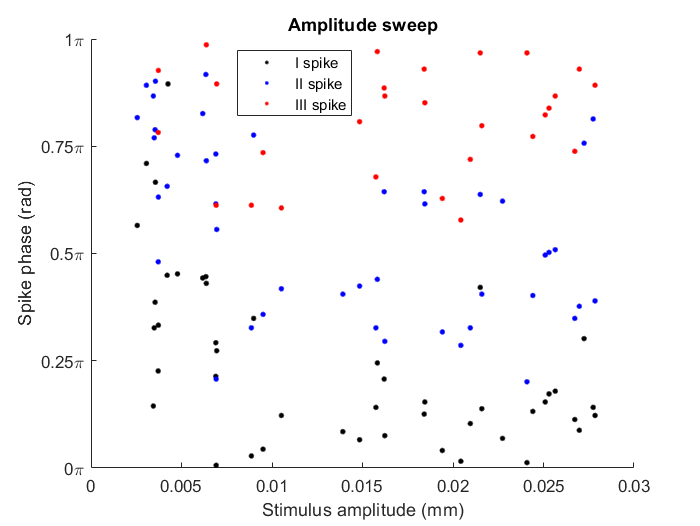

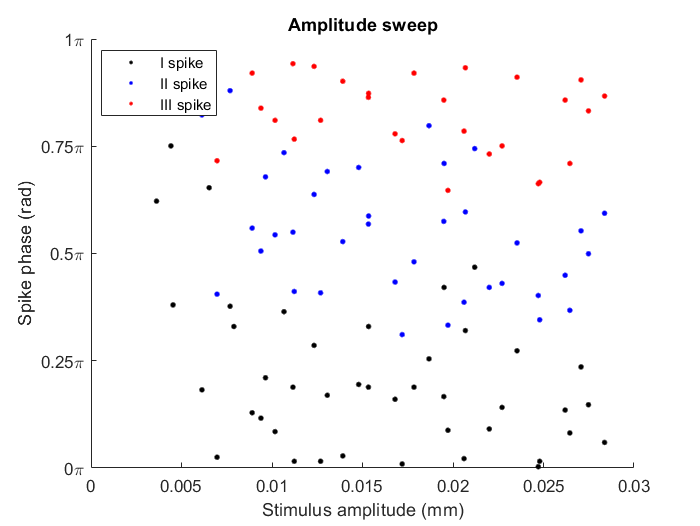

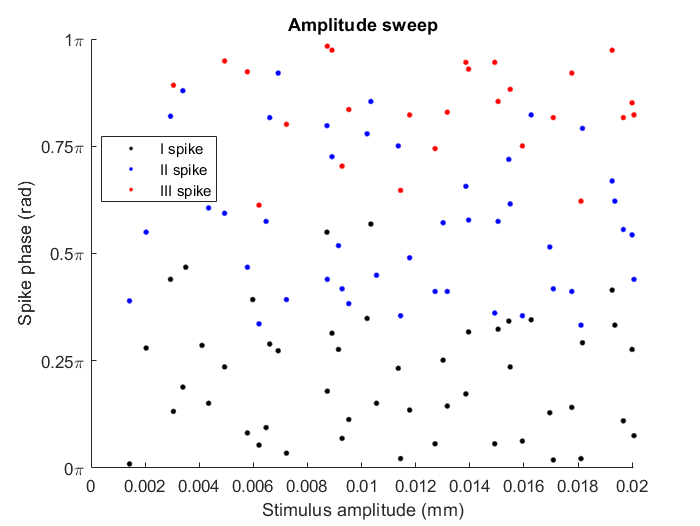

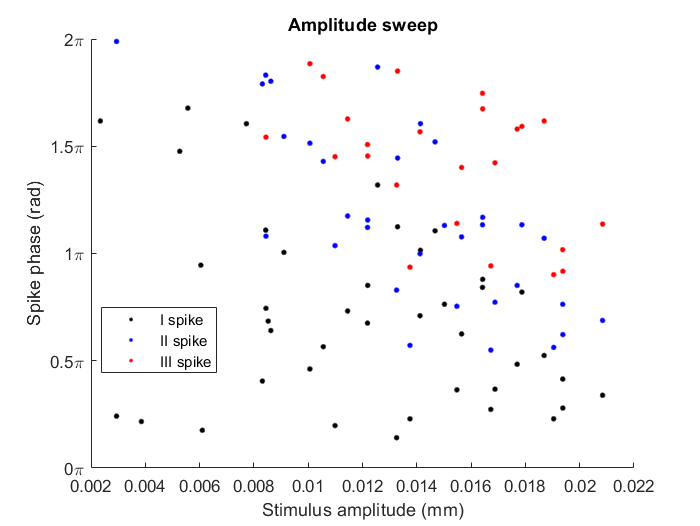

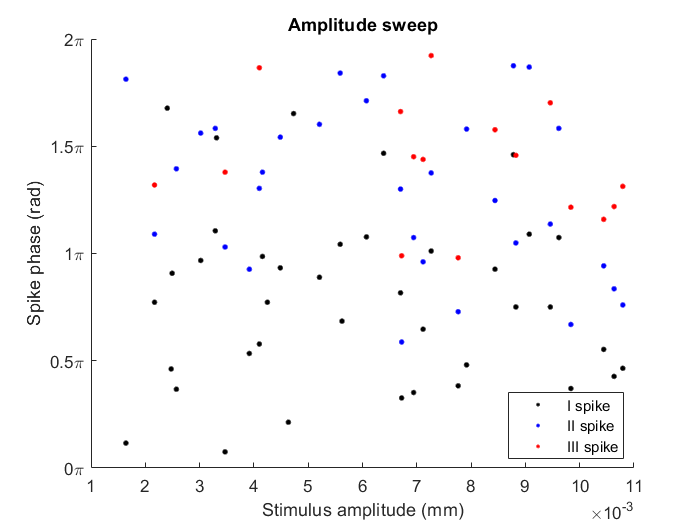

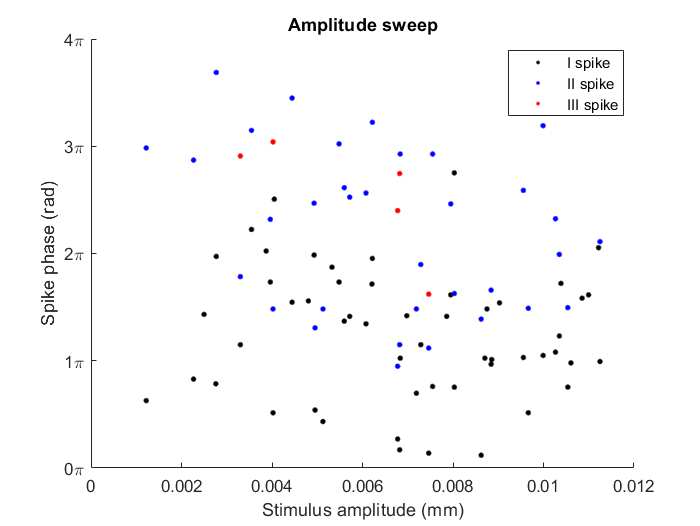

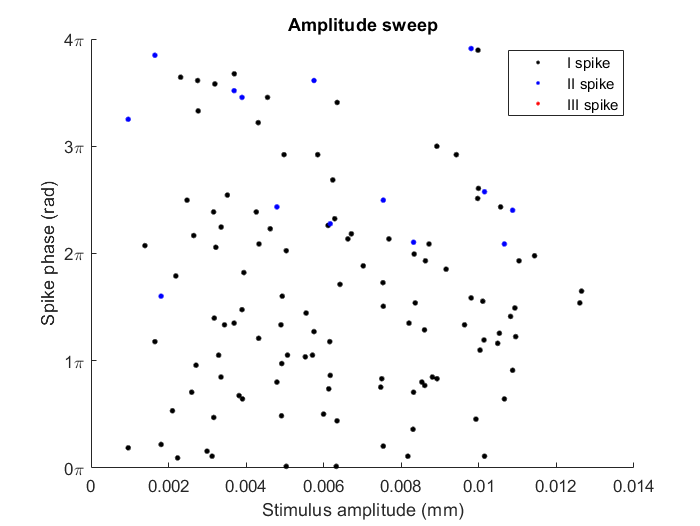

for i=1:18
    fs = ampsweep_meta_struct(i).moth.fs;
    
    ON_dur = ampsweep_meta_struct(i).moth.ON_dur;
    OFF_dur = ampsweep_meta_struct(i).moth.OFF_dur;
    gcfr = ampsweep_meta_struct(i).moth.norm_gcfr(:,OFF_dur*fs:(OFF_dur+ON_dur)*fs);
    f = ampsweep_meta_struct(i).moth.amp_sweep_frq;
    start_stim = OFF_dur*fs;
    stop_stim  = (ON_dur+OFF_dur)*fs;
    
    [I_spike_phase, II_spike_phase, III_spike_phase, I_spike_amp, II_spike_amp, III_spike_amp] = spike_phase(ampsweep_meta_struct(i).moth.antennal_movement(1,:), ampsweep_meta_struct(i).moth.raster(1,:), fs, start_stim, stop_stim, ampsweep_meta_struct(i).moth.stim_type, f);
    figure(); scatter(I_spike_amp,I_spike_phase,100, '.k'); hold on;
    pmin = min([I_spike_phase II_spike_phase III_spike_phase]);
    pmax = max([I_spike_phase II_spike_phase III_spike_phase]);
    pimin = floor(pmin/pi);
    pimax = ceil(pmax/pi);
    ylim([pimin pimax]);
    yticks(pimin:pimax/4:pimax)
    yticklabels( string(pimin:pimax/4:pimax) + "\pi" )
    scatter(II_spike_amp,II_spike_phase, 100,  'b.');
    scatter(III_spike_amp,III_spike_phase, 100, 'r.');
    title('Amplitude sweep');
    ylabel('Spike phase (rad)');
    xlabel('Stimulus amplitude (mm)');
    box off;
    legend('I spike','II spike', 'III spike', 'Location', 'best');
    
    P(i).I_spike = [I_spike_amp', I_spike_phase'];
    P(i).II_spike = [II_spike_amp', II_spike_phase'];
    P(i).III_spike = [III_spike_amp', III_spike_phase'];
end